% Read data
data = readtable('data_part_1.csv');
[x, y] = size(data);

% Extract HS values and composition values
hyperspectralData = table2array(data(2:x, 22:y));
%materialData = table2array(data(2:x, 2:21));
%materialData(isnan(materialData)) = 0;
wavelengths = table2array(data(1, 22:y));

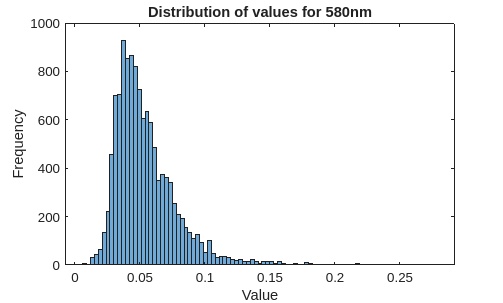

% Visualize distribution of values foe each variable
i = 181;
histogram(hyperspectralData(:,i));
xlabel('Value');
ylabel('Frequency');
title("Distribution of values for "+ wavelengths(i) + "nm");

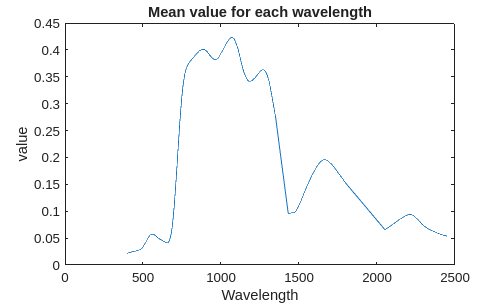


figure;
plot(wavelengths, mean(hyperspectralData, 1));
xlabel("Wavelength");
ylabel("value");
title("Mean value for each wavelength");

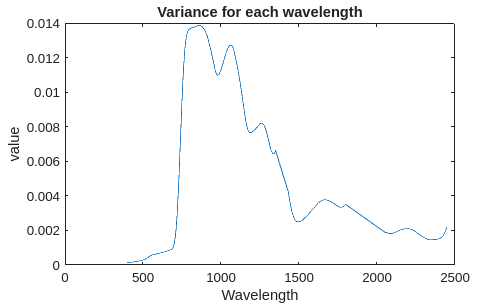


figure;
plot(wavelengths, var(hyperspectralData, [], 1));
xlabel("Wavelength");
ylabel("value");
title("Variance for each wavelength");

% Compute PCA
[coeff, score, latent, tsquared, explained, mu] = pca(hyperspectralData, 'Centered', true, 'VariableWeights','variance');

explained = explained/100;

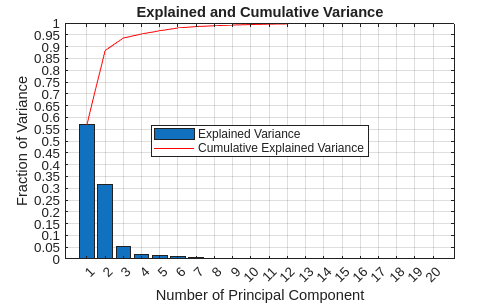

% Plot Explained Variance
figure;
n_plot = 20;
cumulativeExplained = cumsum(explained);
bar(explained(1:n_plot, 1));
hold on;
plot(cumulativeExplained(1:n_plot, 1),'r');
hold off;
xlabel('Number of Principal Component');
ylabel('Fraction of Variance');
ylim([0 1]);
legend('Explained Variance','Cumulative Explained Variance','Location','best');
title('Explained and Cumulative Variance');
xticks(1:n_plot);
yticks(0:0.05:1);
grid on;

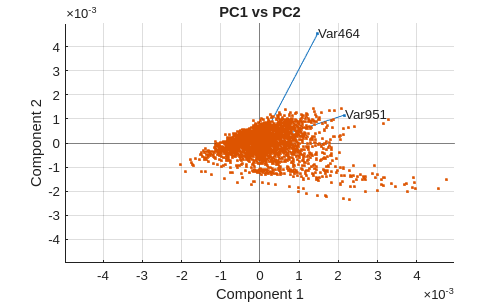

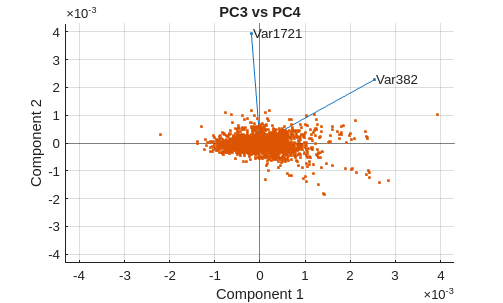

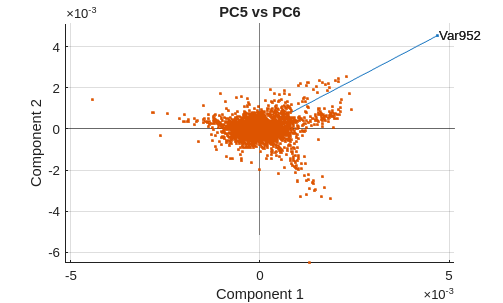

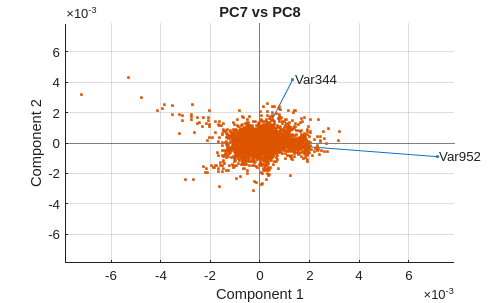

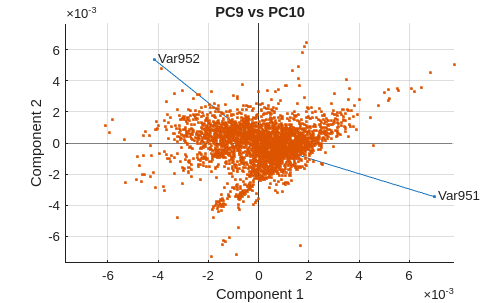

% Biplot (not sure about this part)
numPCs = 10;
topVarIdx = zeros(1, numPCs);

for i = 1:numPCs
    [~, idx] = max(abs(coeff(:,i)));  % index of variable with largest loading
    topVarIdx(i) = idx;
end
for i = 1:2:numPCs
    figure;
    biplot(coeff(topVarIdx(i:i+1),i:i+1), 'Scores', score(:,i:i+1), 'VarLabels', ...
        arrayfun(@(x) ['Var' num2str(x)], topVarIdx(i:i+1), 'UniformOutput', false));
    title(['PC' num2str(i) ' vs PC' num2str(i+1)]);
end